# 2. SPECTRAL ESTIMATION OF EEG SIGNALS DURING SLEEP

In this section, EEG signals will be considered to test different methods for spectral estimation. EEG signals were recorded during sleep. The available data is the following:

• Data files associated with different sleep stages determined by a neurophysiologist: Awake, Stage S1, Stage S2, Slow Wave Activity/Sleep (SWS) and REM.

• In each file there are 21 biological channels recorded during 30 seconds with a sampling frequency of 100 Hz: The first two are EOG and the other 19 channels are EEG signals where the electrodes were located in the following places on the scalp following the international system 10-20: 'Fp1'; 'Fp2'; 'F7'; 'F3'; 'Fz'; 'F4'; 'F8'; 'T3'; 'C3'; 'Cz'; 'C4'; 'T4'; 'T5'; 'P3'; 'Pz'; 'P4'; 'T6'; 'O1' and 'O2' (with this order).

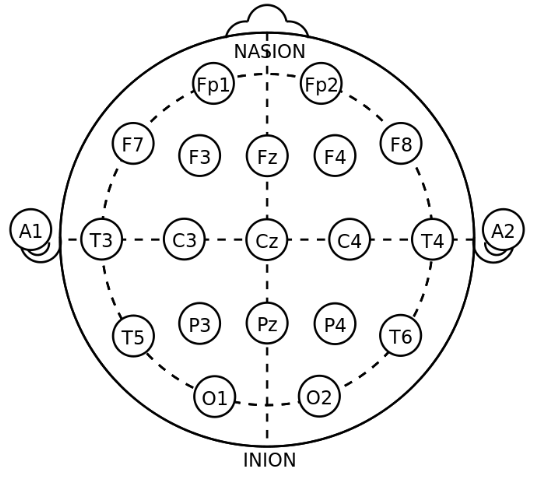

### The objective is to evaluate the impact of the estimator in:

• The PSD functions obtained from EEG signals.

• The relative power indexes: few bands can be more affected than the others of selecting different spectral estimators.

• The brain location of predominant rhythm/band can be also affected or different depending on the spectral estimator.

• The analysis of the relative powers during sleep at different sleep stages where it is expected more sigma activity in the Stage S2, tending to lower frequencies with deeper sleep, more alpha activity during awake etc.

### Load AWAKE data

load('data/EEG_signals-20251023/AWAKE.mat')
% We select the first 5 seconds epoch and the last 19EEG channels:
eegi=signals(1:500,3:21);

Frequency bands come from 0.5 Hz to 35 Hz, thus it is convenient to remove the very low frequency components associated mainly with the movement and other brain activities different to delta rhythms. This action will permit to estimate better the PSD. You can check the estimation twice: high frequency filtering or without filtering:

[b,a]=ellip(6,0.5,40,.4/50,'high');
eeg=filtfilt(b,a,eegi);

% Method 1
% Firstly, the periodogram is estimated considering a FFT with 1000 points:
[Pxx,f]=periodogram(eeg,[],1000,100,'onesided'); %Method 1
% Method 2
[PxxH,f]=periodogram(eeg,hamming(500),1000,100,'onesided'); %Method 2
% Method 3number_segments = 4;
overlap = 0.5;
samples_segment = floor(length(eeg)/(number_segments-(number_segments-1)*overlap));

Unrecognized function or variable 'number_segments'.

[PxxW,f]=pwelch(eeg,samples_segment,floor(samples_segment*overlap),1000,100,'onesided');
% Method 4
Then the PSD is calculated by an AR model using the Burg method: the first selection is a low
order of 2:
[Parb2,f]= pburg(eeg,2,1000,100,'onesided');% Method 4
% Method 5
% and then, a high order of 50:
[Parb50,f]= pburg(eeg,50,1000,100,'onesided'); % Method 5


Finally, orders proposed following the AIC and MDL criteria were selected. As each EEG channel/signal in the first epoch can result a different order, the average order between the 19 channels proposed by each criterion is selected and applied in all EEG channels:

% Methods 6 and 7
for n=1:19
    data1= iddata(eeg(1:250,n),[],100);
    data2= iddata(eeg(251:500,n),[],100);
    V1=arxstruc(data1,data2,[1:60]');
    nnaic(n)=selstruc(V1,'aic');
    nnmdl(n)=selstruc(V1,'mdl');
end

iddata requires System Identification Toolbox.

naic=round(mean(nnaic))
nmdl=round(mean(nnmdl))
[Parbaic,f]= pburg(eeg,naic,1000,100,'onesided'); % Method 6
[Parbmdl,f]= pburg(eeg,nmdl,1000,100,'onesided'); % method 7



## Visualize the signals

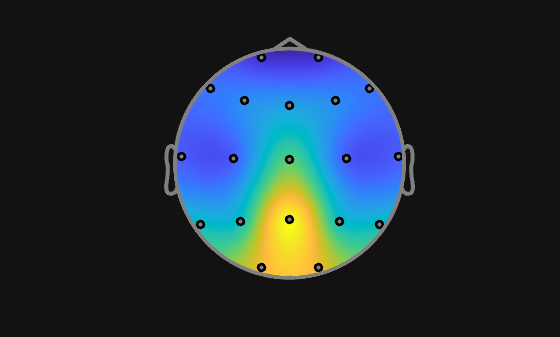

% See the topogram (example)
draw_topogram([0,0,3,4,5,4,3,2,2,9,2,2,7,7,15,7,7,12,12]');

## S1 Stage

clear; clc;
% Load the data
load('data/EEG_signals-20251023/S1.mat');

When downloading the data we have seen that:

- fs = 100Hz

- Signals are of shape (3000, 21)

- Recording time is 30s

### Epoch 1 (5s)

Compare PSD functions for the channels:

- Fz - Channel 7

- Cz - Channel 12

- Pz - Channel 17

For all 7 spectral methods:

- Periodogram 

- Periodogram + HW  

- Welch Periodigram  

- Burg method (low)  

- Burg method (high)  

- Burg method (AIC)  

- Burg method (MDL) 

We have 21 channels. The 2 first are EOG (so we discard them)

channels = signals(1:500, [3, 5, 7]);

figure;
plot(channels)
title('Raw Channels')
xlabel('Samples')
ylabel('Amplitude (microV)')

Plot topogram

draw_topogram([0.704164380228323
0.610894793284649
0.641843369713318
0.568404575158657
0.480829742829948
0.502559318105583
0.574109336831480
0.397640925309503
0.508549796021266
0.476218576127106
0.474838998869208
0.508942239886436
0.293583329482477
0.353030373850745
0.525027504839651
0.602390201614091
0.286600957545983
0.597048627341681
0.684452204695179])

# Changes in Relative Power during Sleep

## Welch Periodogram vs AR MDL

In this exercise we will:

- Compare the power changes across all stages of sleep 

- Both for Welch Periodogram and AR MDL

clc; clear;
% Include the functions folder
addpath('functions/');

fs = 100;                     % Sampling frequency (100 Hz)
nsamples_epoch = fs * 5; % 5-second epoch (500 samples)
num_epochs = 6;
eeg_channel_indices = 3:21;   % Channels 3-21 are the 19 EEG channels
num_channels = 19;

Then we define a setup for iterating through the different datasets and applying the different processing techniques.

% File Paths & Sleep Stages
data_path = 'data/EEG_signals-20251023/'; 
stages = {'AWAKE', 'S1', 'S2', 'SWS', 'REM'}; % Different datasets
num_stages = length(stages);

% --- Spectral Parameters ---
nfft = 1000;              % FFT points
max_ar_order = 60;        % Max AR order to test for MDL

% --- Welch Params ---
num_segments_welch = 4;
overlap_ratio_welch = 0.5;
samples_segment = floor(nsamples_epoch / (num_segments_welch - (num_segments_welch - 1) * overlap_ratio_welch));
overlap_samples = floor(samples_segment * overlap_ratio_welch);

% --- Frequency Bands ---
bands = define_eeg_bands();
band_names = fieldnames(bands);
num_bands = length(band_names);

% Design the high-pass filter
[b_filter, a_filter] = ellip(6, 0.5, 40, 0.4/50, 'high');

% Pre-allocate final result matrices (Channels x Stages)
% In order to fill the results of the different bands and stages of sleep,
% we initialize empty spaces in a struct for filling later.
results_welch = struct();
results_ar_mdl = struct();
for i = 1:num_bands
    results_welch.(band_names{i}) = zeros(num_channels, num_stages);
    results_ar_mdl.(band_names{i}) = zeros(num_channels, num_stages);
end

### Core spectral analysis

- Loops through all five sleep stages.

- Loads the 30-second signal for each.

- Performs an inner loop across the 6 non-overlapping 5-second epochs. 

- For every epoch, it computstage_power_ares the Relative Power using both the** Welch (non-parametric) **method and the **AR-MDL (parametric)** method. 

The **final result** for each stage is the average of the relative powers calculated across all six epochs, providing a **stable PSD estimate**.

%% MAIN LOOP

for i = 1:num_stages
    stage_name = stages{i};
    fprintf('  Processing Stage: %s\n', stage_name);
    
    % Load Data
    file_name = sprintf('%s%s.mat', data_path, stage_name);
    data = load(file_name);
    signals = data.signals;
    
    % Temporary storage for all epochs within this stage (Channels x Epochs)
    stage_power_welch = struct();
    stage_power_ar = struct();
    for b = 1:num_bands
        stage_power_welch.(band_names{b}) = zeros(num_channels, num_epochs);
        stage_power_ar.(band_names{b}) = zeros(num_channels, num_epochs);
    end

    % Loop through Epochs 
    for j = 1:num_epochs
        
        % Extract Epoch
        start_idx = (j-1) * nsamples_epoch + 1;
        end_idx = j * nsamples_epoch;
        eeg_epoch_raw = signals(start_idx:end_idx, eeg_channel_indices);
        
        % Filter Epoch
        eeg_epoch_filtered = filtfilt(b_filter, a_filter, eeg_epoch_raw);
        
        % Method 1: Welch
        [PxxW, f_welch] = pwelch(eeg_epoch_filtered, samples_segment, overlap_samples, nfft, fs, 'onesided');
        rel_power_w = calculate_relative_powers(PxxW, f_welch, bands);
        
        % Method 2: AR (MDL)
        avg_nmdl = get_ar_mdl_order(eeg_epoch_filtered, fs, max_ar_order);
        [PxxAR, f_ar] = pburg(eeg_epoch_filtered, avg_nmdl, nfft, fs, 'onesided'); 
        rel_power_ar = calculate_relative_powers(PxxAR, f_ar, bands);
        
        % Store results for this epoch
        for b = 1:num_bands
            stage_power_welch.(band_names{b})(:, j) = rel_power_w.(band_names{b});
            stage_power_ar.(band_names{b})(:, j) = rel_power_ar.(band_names{b});
        end
    end
    
    % Average Epochs 
    for b = 1:num_bands
        results_welch.(band_names{b})(:, i) = mean(stage_power_welch.(band_names{b}), 2);
        results_ar_mdl.(band_names{b})(:, i) = mean(stage_power_ar.(band_names{b}), 2);
    end
    
end

  Processing Stage: AWAKE
  Processing Stage: S1
  Processing Stage: S2
  Processing Stage: SWS
  Processing Stage: REM


%% PLOT TOPOGRAMS

for b = 1:num_bands
    band_name = band_names{b};
    
    % Welch results
    plot_comparison_topograms(results_welch.(band_name), stages, band_name, 'Welch', ['report/img/topogram_welch_', band_name, '.png']);
    
    % AR(MDL) results
    plot_comparison_topograms(results_ar_mdl.(band_name), stages, band_name, 'AR (MDL)', ['report/img/topogram_ar_', band_name, '.png']);
end